## parameters

syms Amax Vmax t T L real
syms p_i p_f p_i_dot p_f_dot

numerical = true;

% if it doesn't start with 0 velocity ...

% values
if numerical
    Amax = 4;
    Vmax = 2;
    p_i = pi/2;
    p_f = 0;
    p_i_dot = 1.5;
end

## operations

% times
L = abs(p_f - p_i)

L = 1.5708

verse = sign(p_f - p_i)

verse = -1

T = ((L*Amax) + Vmax^2) / (Amax*Vmax)

T = 1.2854

Ts1 = Vmax/Amax

Ts1 = 0.5000

Ts2 = T - Vmax/Amax

Ts2 = 0.7854


if sign(p_i_dot) == -verse

    Tstop = -verse * p_i_dot / Amax
    Lstop = (abs(p_i_dot)/2) * Tstop
    L = L + Lstop

    T = Tstop + ((L*Amax) + Vmax^2) / (Amax*Vmax)
    Ts1 = Tstop + Vmax/Amax
    Ts2 = T - Vmax/Amax
    
end

Tstop = 0.3750

Lstop = 0.2812

L = 1.8520

T = 1.8010

Ts1 = 0.8750

Ts2 = 1.3010


if sign(p_i_dot) == verse
    
    Tant = (Vmax-abs(p_i_dot))/Amax
    T = ((L*Amax) + Vmax^2) / (Amax*Vmax) - Ts1 + Tant
    Ts1 = Tant
    Ts2 = T - Vmax/Amax

end
    


if L < Vmax^2/Amax
    disp("There is no coast, use Bang-Bang!")
end

% accelerations
a1 = verse * Amax;
a2 = 0;
a3 = verse * (-Amax);
atot = [a1; a2; a3];
disp("Acceleration")

Acceleration


disp(string(vpa(a1,5)) + "   for 0 <= t <= " + Ts1)

-4.0   for 0 <= t <= 0.875


disp(string(vpa(a2,5)) + "   for " + Ts1 + " <= t <= " + Ts2)

0.0   for 0.875 <= t <= 1.301


disp(string(vpa(a3,5)) + "   for " + Ts2 + " <= t <= " + T)

4.0   for 1.301 <= t <= 1.801



% velocities
v1 = p_i_dot + verse * (Amax*t);
v2 = p_i_dot + verse * (Amax*Ts1);
v3 = p_i_dot + verse * (Amax*Ts1 - Amax*(t-Ts2));
vtot = [v1; v2; v3];
disp("Velocity")

Velocity


disp(string(vpa(v1,5)) + "   for 0 <= t <= " + Ts1)

1.5 - 4.0*t   for 0 <= t <= 0.875


disp(string(vpa(v2,5)) + "   for " + Ts1 + " <= t <= " + Ts2)

-2.0   for 0.875 <= t <= 1.301


disp(string(vpa(v3,5)) + "   for " + Ts2 + " <= t <= " + T)

4.0*t - 7.2041   for 1.301 <= t <= 1.801



% positions
p1 = p_i + verse * (Amax*t^2/2) + p_i_dot*t;
p2 = p_i + verse * (Vmax*t - Ts1*Vmax/2) + p_i_dot*Ts1/2;
p3 = p_i + verse * (-Amax*(t-T)^2/2 + Vmax*T - Vmax*(Ts1+T-Ts2)/2) + p_i_dot*Ts1/2;
ptot = [p1; p2; p3];
disp("Position")

Position


disp(string(vpa(p1,5)) + "   for 0 <= t <= " + Ts1)

1.5*t - 2.0*t^2 + 1.5708   for 0 <= t <= 0.875


disp(string(vpa(p2,5)) + "   for " + Ts1 + " <= t <= " + Ts2)

3.102 - 2.0*t   for 0.875 <= t <= 1.301


disp(string(vpa(p3,5)) + "   for " + Ts2 + " <= t <= " + T)

2.0*(t - 1.801)^2   for 1.301 <= t <= 1.801


## plot

func = ptot;
n = size(func);
n = n(1);
h = [Ts1 Ts2-Ts1 T-Ts2];
func = subs(func);
h = double(subs(h));
h_plot = [0 sum(h(1:1)) sum(h(1:2)) sum(h(1:3))]

h_plot =          0    0.8750    1.3010    1.8010


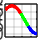

colors = ['r' 'g' 'b'];

% plot position

q_plot = sym(zeros(n,1));
for i = 1:n
    q_plot(i) = matlabFunction(simplify(func(i), steps = 10));
end

for i = 1:n
    fplot(q_plot(i), [h_plot(i) h_plot(i+1)], colors(i), 'Linewidth', 2);
    hold on
end
grid on
hold off
axes = axis;
pad = 0.1 * (axes(4) - axes(3));
axis([axes(1), axes(2), axes(3) - pad, axes(4) + pad]);

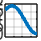



q_plot_unique = piecewise( ...
    h_plot(1) <= t <= h_plot(2), q_plot(1), ...
    h_plot(2) <= t <= h_plot(3), q_plot(2), ...
    h_plot(3) <= t <= h_plot(4), q_plot(3) ...
);
fplot(q_plot_unique, [0 T], 'Linewidth', 2);
grid on
axes = axis;
pad = 0.1 * (axes(4) - axes(3));
axis([axes(1), axes(2), axes(3) - pad, axes(4) + pad]);

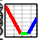



% plot velocity

q_dot_plot = sym(zeros(n,1));
for i = 1:n
    q_dot_plot(i) = simplify(func(i), steps = 10);
    q_dot_plot(i) = matlabFunction(diff(q_dot_plot(i), t));
end

for i = 1:n
    fplot(q_dot_plot(i), [h_plot(i) h_plot(i+1)], colors(i), 'Linewidth', 2);
    hold on
end
grid on
hold off
axes = axis;
pad = 0.1 * (axes(4) - axes(3));
axis([axes(1), axes(2), axes(3) - pad, axes(4) + pad]);

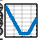



q_dot_plot_unique = piecewise( ...
    h_plot(1) <= t <= h_plot(2), q_dot_plot(1), ...
    h_plot(2) <= t <= h_plot(3), q_dot_plot(2), ...
    h_plot(3) <= t <= h_plot(4), q_dot_plot(3) ...
);
fplot(q_dot_plot_unique, [0 T], 'Linewidth', 2);
grid on
axes = axis;
pad = 0.1 * (axes(4) - axes(3));
axis([axes(1), axes(2), axes(3) - pad, axes(4) + pad]);

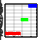



% plot acceleration

q_2dot_plot = sym(zeros(n,1));
for i = 1:n
    q_2dot_plot(i) = simplify(func(i), steps = 10);
    q_2dot_plot(i) = matlabFunction(diff(q_2dot_plot(i), t, 2));
end

for i = 1:n
    fplot(q_2dot_plot(i), [h_plot(i) h_plot(i+1)], colors(i), 'Linewidth', 2);
    hold on
end
grid on
hold off
axes = axis;
pad = 0.1 * (axes(4) - axes(3));
axis([axes(1), axes(2), axes(3) - pad, axes(4) + pad]);

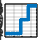



q_2dot_plot_unique = piecewise( ...
    h_plot(1) <= t <= h_plot(2), q_2dot_plot(1), ...
    h_plot(2) <= t <= h_plot(3), q_2dot_plot(2), ...
    h_plot(3) <= t <= h_plot(4), q_2dot_plot(3) ...
);
fplot(q_2dot_plot_unique, [0 T], 'Linewidth', 2);
grid on
axes = axis;
pad = 0.1 * (axes(4) - axes(3));
axis([axes(1), axes(2), axes(3) - pad, axes(4) + pad]);